clc;
clear;

load("SegmentationValues.mat")
fs = 1000;
%Parameters for MFCCs
Tw = 25            %Analysis frame duration (ms) 

Tw = 25

Ts = 10;           %Analysis frame shift (ms)
alpha = 0.97;      %Preemphasis coefficient
R = [1 500];       %Frequency range to consider
M = 20;            %Number of filterbank channels 
C = 13;            %Number of cepstral coefficients
L = 22;            %Cepstral sine lifter parameter
hamming = @(N)(0.54-0.46*cos(2*pi*[0:N-1].'/(N-1)));

i = 40;
j = 4;

CC_S1       = mfcc(S1{i},       fs, Tw, Ts, alpha, hamming, R, M, C, L);
CC_Systole  = mfcc(Systole{i},  fs, Tw, Ts, alpha, hamming, R, M, C, L);
CC_S2       = mfcc(S2{i},       fs, Tw, Ts, alpha, hamming, R, M, C, L);
CC_Diastole = mfcc(Diastole{i}, fs, Tw, Ts, alpha, hamming, R, M, C, L);

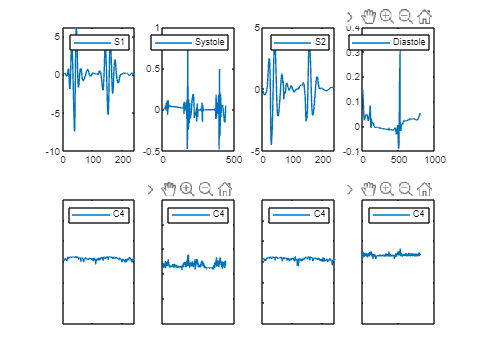

%PLOTTING S1 AND CC_S1
subplot(2,4,1)
plot(S1{i})
legend("S1")
subplot(2,4,5)
plot(CC_S1(j,:))
set(gca,'XTickLabel',[],'YTickLabel',[])
legend("C" + j)
%PLOTTING SYSTOLE AND CC_SYSTOLE
subplot(2,4,2)
plot(Systole{i})
legend("Systole")
subplot(2,4,6)
plot(CC_Systole(j,:))
set(gca,'XTickLabel',[],'YTickLabel',[])
legend("C" + j)
%PLOTTING S2 AND CC_S2
subplot(2,4,3)
plot(S2{i})
legend("S2")
subplot(2,4,7)
plot(CC_S2(j,:))
set(gca,'XTickLabel',[],'YTickLabel',[])
legend("C" + j)
%PLOTTING Diastole AND CC_Diastole
subplot(2,4,4)
plot(Diastole{i})
legend("Diastole")
subplot(2,4,8)
plot(CC_Diastole(j,:))
legend("C" + j)
set(gca,'XTickLabel',[],'YTickLabel',[])

function [ CC, FBE, frames ] = mfcc( speech, fs, Tw, Ts, alpha, ~, R, M, N, L)

   if( max(abs(speech))<=1 ), speech = speech * 2^15;
   end
    Nw = round( 1E-3*Tw*fs );    % frame duration (samples)
    Ns = round( 1E-3*Ts*fs );    % frame shift (samples)
    nfft = 2^nextpow2( Nw );     % length of FFT analysis 
    K = nfft/2+1;                % length of the unique part of the FFT 
    %% HANDY INLINE FUNCTION HANDLES
    % Forward and backward mel frequency warping (see Eq. (5.13) on p.76 of [1]) 
    % Note that base 10 is used in [1], while base e is used here and in HTK code
    hz2mel = @( hz )( 1127*log(1+hz/700) );     % Hertz to mel warping function
    mel2hz = @( mel )( 700*exp(mel/1127)-700 ); % mel to Hertz warping function
    % Type III DCT matrix routine (see Eq. (5.14) on p.77 of [1])
    dctm = @( N, M )( sqrt(2.0/M) * cos( repmat([0:N-1].',1,M) ...
                                       .* repmat(pi*([1:M]-0.5)/M,N,1) ) );
    % Cepstral lifter routine (see Eq. (5.12) on p.75 of [1])
    ceplifter = @( N, L )( 1+0.5*L*sin(pi*[0:N-1]/L) );
    %% FEATURE EXTRACTION 
    % Preemphasis filtering (see Eq. (5.1) on p.73 of [1])
    speech = filter( [1 -alpha], 1, speech ); % fvtool( [1 -alpha], 1 );
    % Framing and windowing (frames as columns)
%     frames = vec2frames( speech, Nw, Ns, 'cols', window, false );
    frames = speech;
    % Magnitude spectrum computation (as column vectors)
    MAG = abs( fft(frames,nfft,1) ); 
    % Triangular filterbank with uniformly spaced filters on mel scale
    H = trifbank( M, K, R, fs, hz2mel, mel2hz ); % size of H is M x K 
    % Filterbank application to unique part of the magnitude spectrum
    FBE = H * MAG(1:K,:); % FBE( FBE<1.0 ) = 1.0; % apply mel floor
    % DCT matrix computation
    DCT = dctm( N, M );
    % Conversion of logFBEs to cepstral coefficients through DCT
    CC =  DCT * log( FBE );
    % Cepstral lifter computation
    lifter = ceplifter( N, L );
    % Cepstral liftering gives liftered cepstral coefficients
    CC = diag( lifter ) * CC; % ~ HTK's MFCCs
% EOF

end